%use fibinochi
T=[1];  
layers=1000;
for row=2:layers
    for i=1:row
        if(i==(1||row))
            T(1,i)=0;
            T(row,i)=1;
        else
            T(1,i)=0;
            T(row,i)=T(row-1,i-1)+T(row-1,i);
        end
    end
end
%{
hold on
for i=1:layers
    scatter(T(1,:)+i,asin(sin(T(i,:))),3,'black','filled');
end
xlim([200.0 layers]);
ylim([-pi/2 pi/2]);
hold off
%}
above=1;
below=1;
difference=[]


difference =

     []



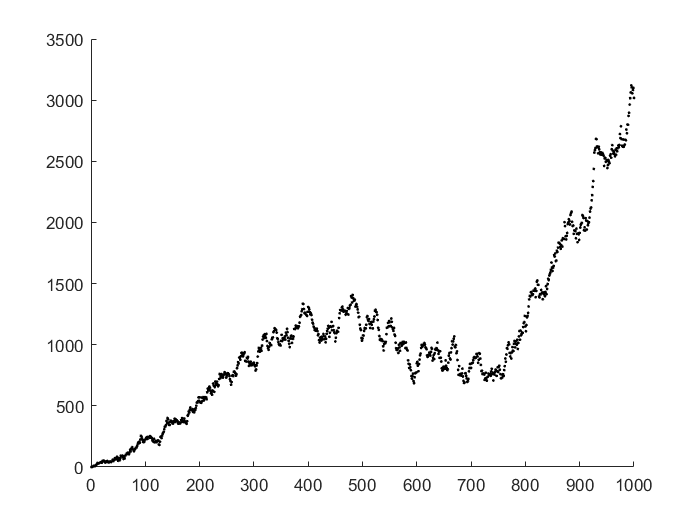

for i=1:layers
    for a=1:length(T(i,:))
       if(asin(sin(T(i,a)))>0)
            above=above+1;
       elseif(asin(sin(T(i,a)))<0)
            below=below+1;
       end 
       difference(i)=above-below;
    end
end
scatter(1:layers,difference,3,'black','filled');